# Cobb-Douglas Production Function

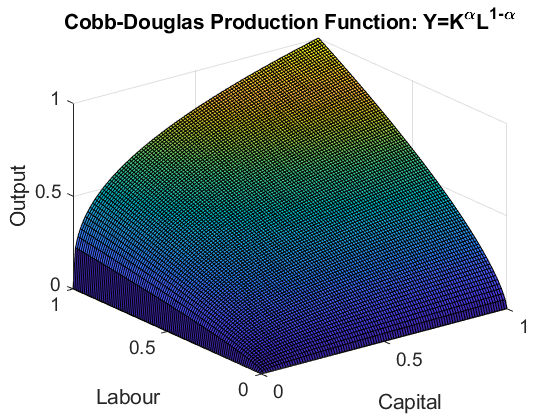

k=0:0.01:1;
l=0:0.01:1;
alppha=0.33;

[K,L]=meshgrid(k,l);
Y=K.^alppha.*L.^(1-alppha);
figure;
surf(K,L,Y)

xlabel('Capital','FontSize',14)
ylabel('Labour','FontSize',14)
zlabel('Output','FontSize',14)

title('Cobb-Douglas Production Function: Y=K^{\alpha}L^{1-\alpha}','FontSize',14);
set(gca,'FontSize',14);

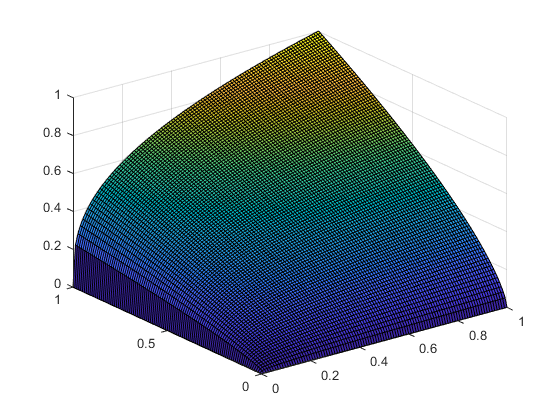

%print -depsc2 CobbDouglasGraphzbuffer %% -zbuffer '-bestfit' or '-fillpage'

figure
surfc(K,L,Y)

alpha(0.3)

Array indices must be positive integers or logical values.

'alpha' appears to be both a function and a variable. If this is unintentional, use 'clear alpha' to remove the variable 'alpha' from the workspace.

shading interp

xlabel('Capital','FontSize',14)
ylabel('Labour','FontSize',14)
zlabel('Output','FontSize',14)

title('Cobb-Douglas Production Function: Y=K^{\alpha}L^{1-\alpha}');

%bottom triangle
X = [0.5; 0; 0.5];
Y = [0; 0.6; 0];
Z = [0; 0 ; 1];
C = [0.5000 ;
     1.0000 ;
     0.3330 ];
     
%top triangle
X1 = [0.8; 0; 0.8];
Y1 = [0; 0.9; 0];
Z1 = [0; 1 ; 1];
     
hold on
%figure
fill3(X,Y,Z,C)
%figure
fill3(X1,Y1,Z1,C)

view(2)
box on
grid on

text(0.58, 0.3,'\leftarrow isocost line', 'fontsize', 14)
text(0.4, 0.7,'isoquants \rightarrow', 'fontsize', 14)

hold off

# Production function for given labour input

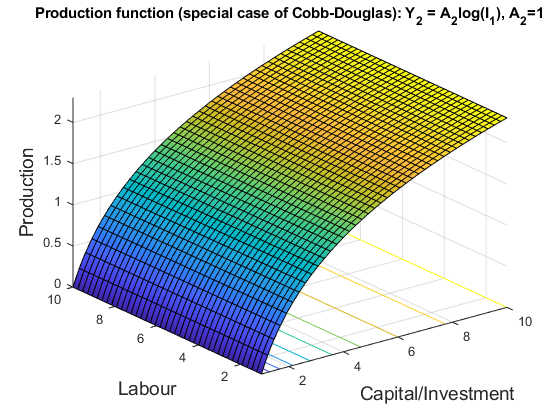

A=1;
syms I
Y = A*log(I);
fsurf(Y, [1 10], 'MeshDensity', 40, 'ShowContours','on')
%view(60,20)
xlabel('Capital/Investment','FontSize',14)
ylabel('Labour','FontSize',14)
zlabel('Production','FontSize',14)
title('Production function (special case of Cobb-Douglas): Y_2 = {A_2}log(I_1), A_2=1')

hold off

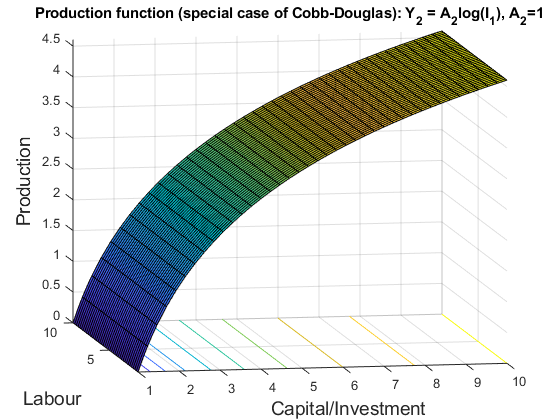

A=2;
syms I
Y = A*log(I);
fsurf(Y, [1 10], 'MeshDensity', 40, 'ShowContours','on')
view(-10,10)
xlabel('Capital/Investment','FontSize',14)
ylabel('Labour','FontSize',14)
zlabel('Production','FontSize',14)
title('Production function (special case of Cobb-Douglas): Y_2 = {A_2}log(I_1), A_2=1')

hold off

# 2D production function (intensive form) 

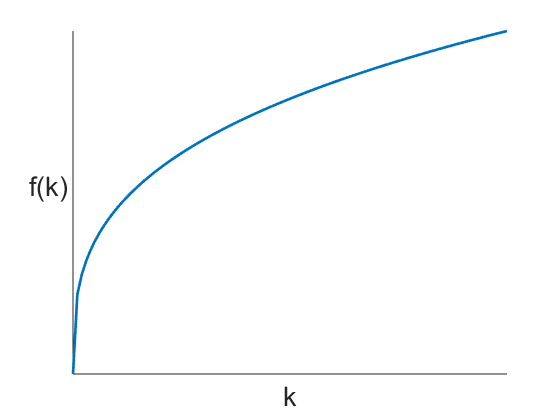

%Essentially: intensive form simply means that we've divided the Cobb-Douglas function
%through by labour --> the main idea follows from our production function:
%Q_2 = A_2*F(I_1) = A_2*(I_1)^{\alpha} , where 0 < \alpha < 1
%acurve=alppha;
acurve=0.3175;
k=0:0.01:1;
yeffl = k.^acurve;
figure
hold on
plot(k, yeffl, 'LineWidth', 2)

%ylabel('f(k)','Rotation',0,'VerticalAlignment','top')
ylabel('f(k)','Rotation',0,'HorizontalAlignment','right')

xlabel('k','FontSize',20 , 'LineWidth', 2)
ylabel('f(k)','FontSize', 20 , 'LineWidth', 2)
xticklabels('')
yticklabels('')
xticks([])
yticks([])

hold off

## Marginal product of capital (MPK)

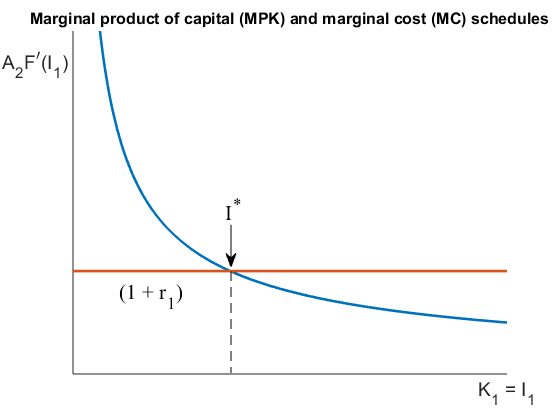

%%%% MPK (intensive form)

acurve=0.3175;
syms x a
x = a.^acurve;
dyeffl = diff(x); %% differentiates F with respect to the variable var.

figure
fplot(dyeffl, 'LineWidth', 2);
hold on
z = 0:5;
z1 = [0.3 0.3 0.3 0.3 0.3 0.3];
plot(z, z1, 'LineWidth', 2)
axis([0 3 0 1])
xticks([])
yticks([])
xlabel('K_1 = I_1', 'fontsize', 14, 'FontName', 'serif', 'Position', [3 -0.01])
ylabel('A_{2}F^{\prime}(I_1)', 'fontsize', 14, 'Rotation', 0, 'fontname', 'serif', 'Position', [-0.025 0.85], 'HorizontalAlignment', 'right')
title('Marginal product of capital (MPK) and marginal cost (MC) schedules', 'FontSize', 12)

%text(0.1, 0.25,'(1 + r_1)', 'fontsize', 16);
%text(1.05, 0.38,'\downarrow k^*', 'fontsize', 16)

annotation('textarrow',[0.4125 0.4125],[0.465 0.365], 'String', 'I^*','fontsize', 16, 'fontname', 'serif')
annotation('textbox',[.2 .25 0.3 0.1], 'String', '(1 + r_1)' ,'FitBoxToText','on', 'EdgeColor','none','fontsize', 16, 'fontname', 'serif')
annotation('line',[0.4125 0.4125],[0.354 0.1119], 'LineStyle', '--')
box off
hold off

## high versus low alpha (share of capital in production)

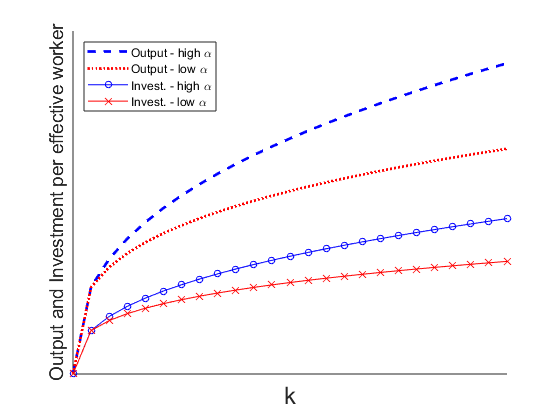

k = linspace(0, 25, 25);

%acurve=alppha;
acurveH=0.4;
acurveL=0.3;
sav=0.5;
%sav=1;

beven = 0.15*k;

yefflH = k.^acurveH;
yefflL = k.^acurveL;
invH = sav*yefflH;
invL = sav*yefflL;

figure
hold on
plot(k, yefflH, 'LineStyle', '--', 'Color', 'b','DisplayName','Output - high \alpha', 'LineWidth', 2);
plot(k, yefflL, 'LineStyle', ':', 'Color', 'r','DisplayName','Output - low \alpha', 'LineWidth', 2);
plot(k, invH, 'LineStyle', '-', 'Marker', 'o', 'MarkerSize', 5, 'Color', 'b','DisplayName','Invest. - high \alpha', 'LineWidth', 0.1);
plot(k, invL, 'LineStyle', '-', 'Marker', 'x', 'MarkerSize', 6, 'Color', 'r','DisplayName','Invest. - low \alpha', 'LineWidth', 0.1);
%plot(k, beven, 'LineStyle', '-', 'Color', 'g','DisplayName','Breakeven invest.', 'LineWidth', 2);

legend('show','Location','northwest');

%ylabel('Output and Investment per effective worker','Rotation',0,'VerticalAlignment','top')

xlabel('k','FontSize',18 )
ylabel('Output and Investment per effective worker','FontSize', 14)

xticklabels('')
yticklabels('')
xticks([])
yticks([])
hold off

## differentiate nth diff(F,var, n)

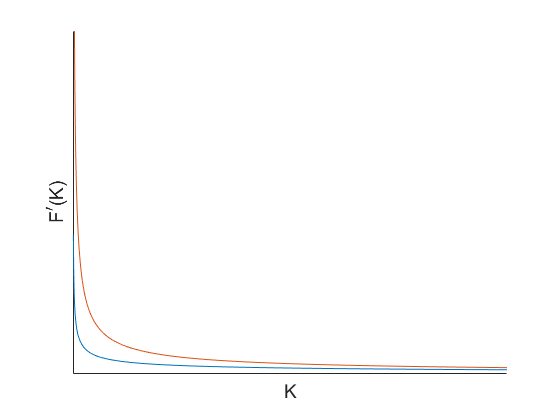

acurveH=0.5;
acurveL=0.3;
syms qH qL K
qH = K.^acurveH;
dyefflH = diff(qH); %% differentiates F with respect to the variable var.
qL = K.^acurveL;
dyefflL = diff(qL);

figure
fplot(dyefflH, [0 0.01]);
hold on
fplot(dyefflL, [0 0.01]);

%text(40,0.15,'\alpha=0.4')
%text(10,0.1,'\alpha=0.3')
xticks([])
yticks([])
xlabel('K', 'FontSize', 14)
ylabel('F^{\prime}(K)', 'FontSize', 14)
%a = gca;
%a.TickLabelInterpreter = 'latex';
%a.Box = 'on';
%a.BoxStyle = 'full';
%xlabel('$x$','Interpreter','latex')
box off
hold off

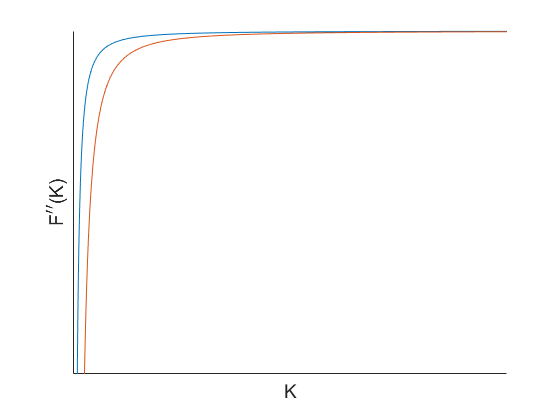


ddyefflH = diff(qH,2);
ddyefflL = diff(qL,2);
figure
fplot(ddyefflH, [0 0.01]);
hold on
fplot(ddyefflL, [0 0.01]);
xticks([])
yticks([])
xlabel('K', 'FontSize', 14)
ylabel('F^{\prime{\prime}}(K)', 'FontSize', 14)
box off
hold off

# Quick version production function & contours

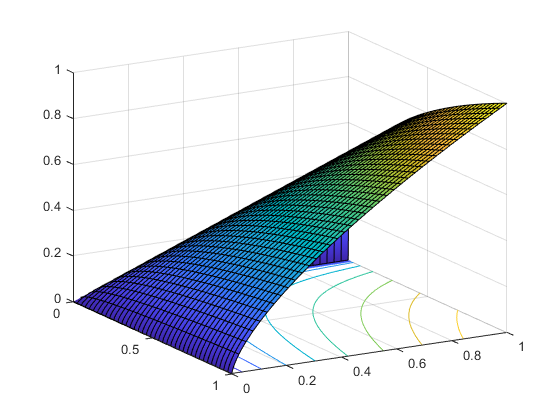

alppha=0.3175;
syms Ks Ls
fsurf(Ks.^alppha.*Ls.^(1-alppha), [0 1], 'MeshDensity', 40, 'ShowContours','on')
view(60,20)

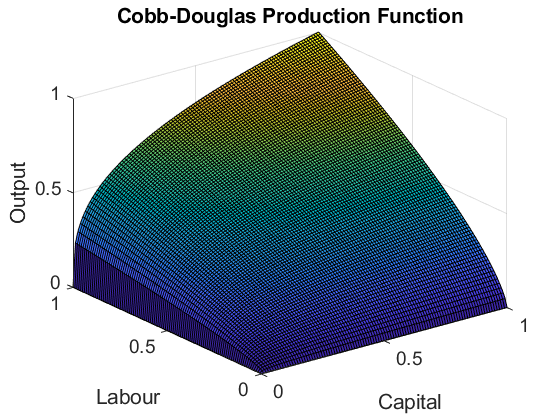


%%% 
k= 0:0.01:1;
l= 0:0.01:1;
alppha=0.3175;

[K,L]=meshgrid(k,l);
Y=K.^alppha.*L.^(1-alppha);
figure;
surf(K,L,Y)

xlabel('Capital','FontSize',14)
ylabel('Labour','FontSize',14)
zlabel('Output','FontSize',14)

h=title('Cobb-Douglas Production Function');

set(h,'FontSize',14);
set(gca,'FontSize',14);

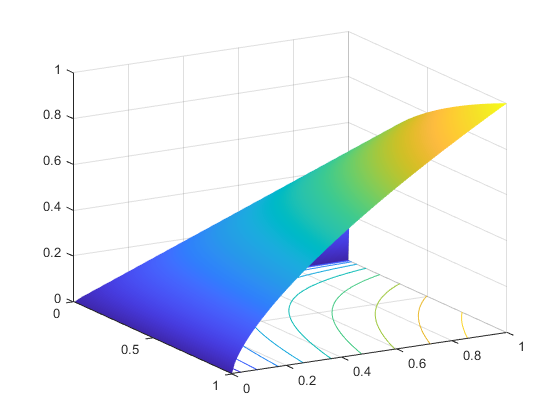


%print -depsc2 CobbDouglasGraphzbuffer %% -zbuffer '-bestfit' or '-fillpage'
figure()
surfc(K,L,Y)
view(60,20)
shading interp

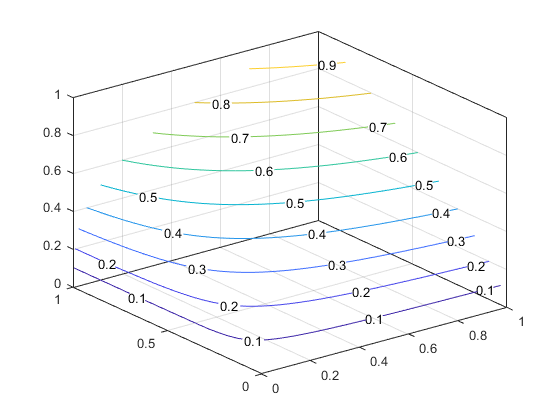


figure()
[c,h]=contour3(K,L,Y);
clabel(c,h);

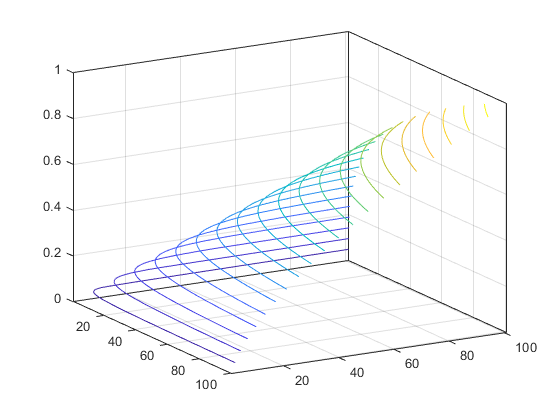

contour3(Y,20);
view(60,20);

# Investment Schedule

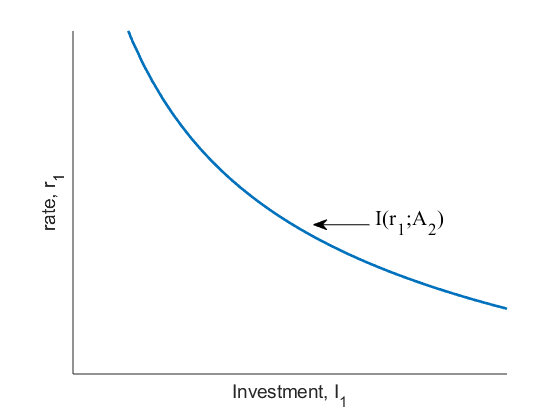

acurve=0.45;
A = 1;
syms I rate
I = A.*rate.^(-acurve);

figure
fplot(I, 'LineWidth', 2);
hold on
axis([0.1 1 0.765 2])

xticks([])
yticks([])
xlabel('Investment, I_1', 'fontsize', 14)
ylabel('rate, r_1', 'fontsize', 14, 'Rotation', 90)

annotation('textarrow',[0.66 0.56],[0.465 0.465], 'String', 'I(r_1;A_2)','fontsize',16, 'VerticalAlignment', 'baseline', 'FontName', 'Serif')
box off

hold off

# Savings Schedule

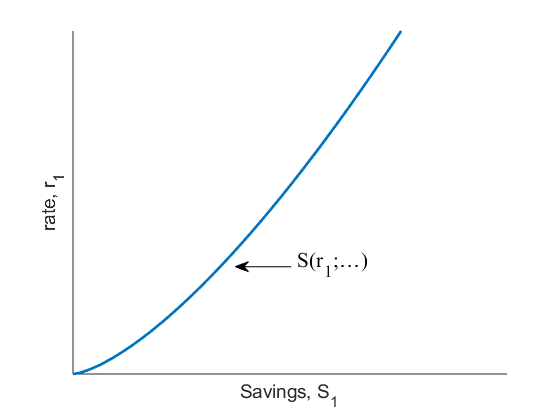

acurve=0.45;
A = 3;
syms S rate
S = A.*rate.^(1+acurve);
figure
fplot(S,'LineWidth', 2);
hold on
axis([0 1 0 2])

xticks([])
yticks([])
xlabel('Savings, S_1', 'fontsize', 14)
ylabel('rate, r_1', 'fontsize', 14, 'Rotation', 90)
%text(0.1, 0.25,'(1 + r_1)', 'fontsize', 16);
%text(1.05, 0.38,'\downarrow k^*', 'fontsize', 16)

annotation('textarrow',[0.52 0.42],[0.365 0.365], 'String', 'S(r_1;\ldots)','fontsize',16, 'VerticalAlignment', 'baseline', 'FontName', 'Serif')
%annotation('textbox',[.2 .25 0.3 0.1], 'String', '(1 + r_1)' ,'FitBoxToText','on', 'EdgeColor','none','fontsize',16)
%annotation('line',[0.4125 0.4125],[0.354 0.1119], 'LineStyle', '--')
box off

hold off

# Savings-Investment Schedule

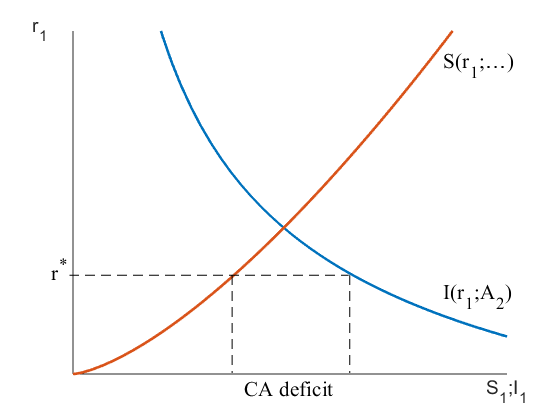

icurve=0.5;
Ai = 0.9;
syms I rate
I = Ai.*rate.^(-icurve);

figure
fplot(I, 'LineWidth', 2);
hold on

scurve=0.45;
As = 1.5;
syms S rate
S = 0.765 + As.*rate.^(1 + scurve);

fplot(S, 'LineWidth', 2);
hold on
axis([0 1 0.765 2])

xticks([])
yticks([])
xlabel('S_1;I_1', 'fontsize', 14, 'Position', [1 0.7625])
ylabel('r_1', 'fontsize', 14, 'Rotation', 0, 'Position', [-0.075 1.95])
%text(0.1, 0.25,'(1 + r_1)', 'fontsize', 16);
%text(1.05, 0.38,'\downarrow k^*', 'fontsize', 16)

annotation('textbox',[.78 .8 .1 .1], 'String', 'S(r_1;\ldots)','FitBoxToText','on', 'EdgeColor','none','fontsize',16, 'fontname', 'serif')
annotation('textbox',[.78 .25 .1 .1], 'String', 'I(r_1;A_2)' ,'FitBoxToText','on', 'EdgeColor','none','fontsize',16, 'fontname', 'serif')

annotation('line',[0.4145 0.4145],[0.3445 0.1119], 'LineStyle', '--')
annotation('line',[0.6245 0.6245],[0.3445 0.1119], 'LineStyle', '--')
annotation('line',[0.124 0.6225],[0.3445 0.3445], 'LineStyle', '--')
annotation('textbox',[.4245 .02 .1 .1], 'String', 'CA deficit','FitBoxToText','on', 'EdgeColor','none','fontsize',16, 'fontname', 'serif')
annotation('textbox',[.08 .31 .1 .1], 'String', 'r^*' ,'FitBoxToText','on', 'EdgeColor','none','fontsize', 16, 'fontname', 'serif')


box off

hold off

# Continuous compounding

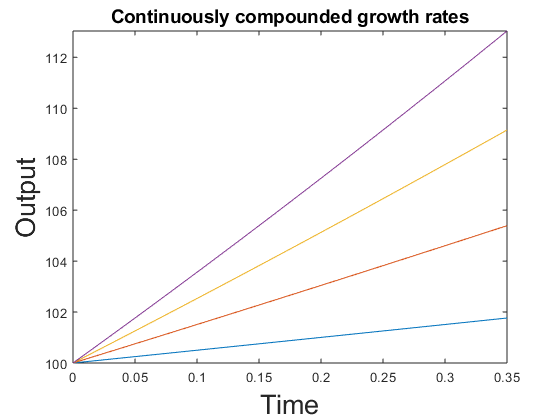

syms time X

%g=0:0.05:0.35;
g=0.05:0.1:0.35;
%time=0:0.25:10;

X = 100*exp(g.*time);
fplot(X, [0 0.35]);

xlabel('Time','FontSize',20 , 'LineWidth', 2)
ylabel('Output','FontSize', 20 , 'LineWidth', 2)

h=title('Continuously compounded growth rates');
set(h,'FontSize',14);